clc;
clear all;
close all;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');

Adding matlab path to: /media/jorge/98DC550DDC54E752/code/SIM/code


#### Parameters

Parameters

total_iteration = 1

Wireless packet type: SC


N_y = 4

M_x = 15

M_y = 15

zeta =     0.9000    0.9100    0.9200    0.9300    0.9400    0.9500    0.9600    0.9700    0.9800    0.9900


T_coh = 0.0066

T = 4096

T = 144

SNR_dB = 11.6443

load G_vs_eta_N_16_Zeta_0_8_to_1

#### Evaluating the Loss function per iteration

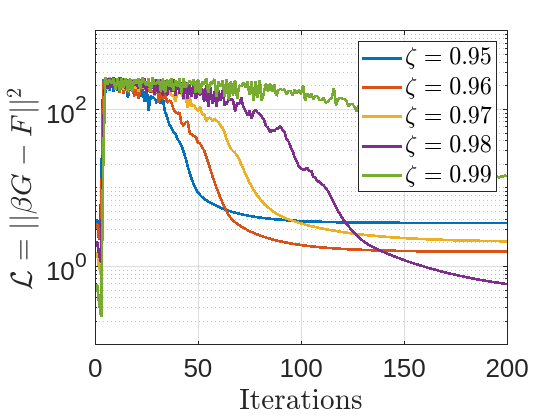


figure;
% semilogy(loss_hist{1},'LineWidth',2); grid on; hold on;
% semilogy(loss_hist{2},'LineWidth',2); grid on; hold on;
% semilogy(loss_hist{3},'LineWidth',2);
% semilogy(loss_hist{4},'LineWidth',2);
% % semilogy(loss_hist{5},'LineWidth',2);
semilogy(loss_hist{6},'LineWidth',2);hold on; grid on;
semilogy(loss_hist{7},'LineWidth',2); 
semilogy(loss_hist{8},'LineWidth',2);
semilogy(loss_hist{9},'LineWidth',2);
semilogy(loss_hist{10},'LineWidth',2);
xlabel('Iterations','Interpreter','latex');
ylabel('$\mathcal{L}=||\beta G-F||^2$','Interpreter','latex');
legend({strcat('$\zeta=',num2str(zeta(6)),'$'),...
    strcat('$\zeta=',num2str(zeta(7)),'$'),...
    strcat('$\zeta=',num2str(zeta(8)),'$'),...
    strcat('$\zeta=',num2str(zeta(9)),'$'),...
    strcat('$\zeta=',num2str(zeta(10)),'$')},'Interpreter','latex')
set(gca,'FontSize',font);

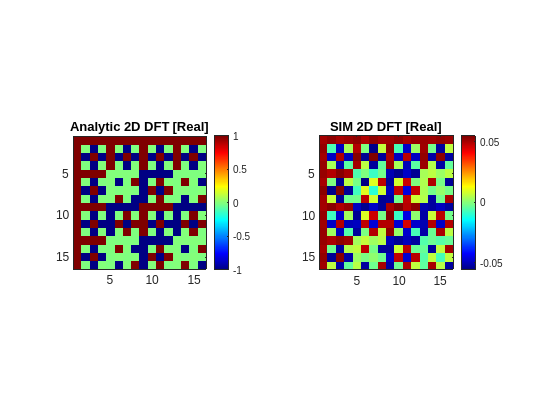




% Evaluating target 2D-DFT matrix F in Eq. (8) as
F = dft2_matrix(N_x, N_y);   % N_xN_y x N_xN_y, matches paper definition. [Eq. (11), 1]

figure
subplot 121
imagesc(real(F))
axis image
colormap jet
colorbar
title('Analytic {2D DFT} [Real]')

subplot 122
G=G_vs_eta{9};
imagesc(-real(G))
axis image
colormap jet
colorbar
title('{SIM 2D DFT} [Real]')

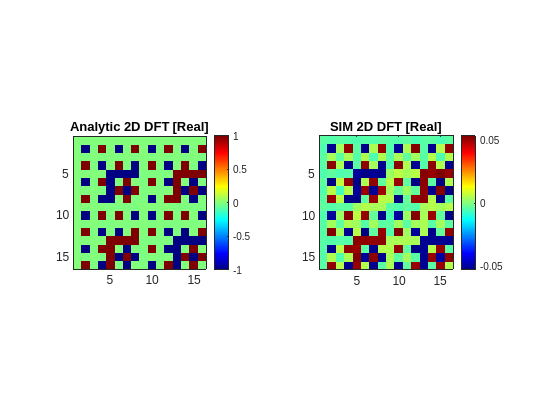


figure
subplot 121
imagesc(imag(F))
axis image
colormap jet
colorbar
title('Analytic {2D DFT} [Real]')

subplot 122
G=G_vs_eta{9};
imagesc(-imag(G))
axis image
colormap jet
colorbar
title('{SIM 2D DFT} [Real]')

function F = dft2_matrix(Nx, Ny)
% Matches eq. (11): F(n,nhat) = exp(-j2pi (nx-1)(nhx-1)/Nx) * exp(-j2pi (ny-1)(nhy-1)/Ny)
    N = Nx*Ny;
    F = zeros(N,N);
    for n = 1:N
        [nx, ny] = ind2sub([Nx, Ny], n); % careful: Matlab ind2sub uses column-major; we want nx fastest
        % We'll define our own mapping: nx = mod(n-1,Nx)+1, ny = floor((n-1)/Nx)+1
        nx = mod(n-1, Nx) + 1;
        ny = floor((n-1)/Nx) + 1;
        for nh = 1:N
            nhx = mod(nh-1, Nx) + 1;
            nhy = floor((nh-1)/Nx) + 1;
            F(n,nh) = exp(-1j*2*pi*(nx-1)*(nhx-1)/Nx) * exp(-1j*2*pi*(ny-1)*(nhy-1)/Ny);
        end
    end
end

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function Lval = loss_from_xi(xi, WL, W, W0, F)

    % Forward model
    [G, ~] = forward_G(WL, W, W0, xi);

    % Optimal beta (Eq. 21)
    g = G(:);
    f = F(:);
    beta = (g' * f) / (g' * g);

    % Loss (Eq. 12)
    E = beta*G - F;
    Lval = norm(E,'fro')^2;
end

function [G, Gamma] = forward_G(WL, W, W0, xi)
    % This function evaluates all the products of Gamma_l*W_l as follows from Eq. (2)
    % Construct Gamma matrices and forward multiply to get G.
    L = numel(xi);
    Gamma = cell(L,1);
    
    %Evaluates the Gamma matrix per layer as follows from Eq. (3)
    for l = 1:L
        Gamma{l} = diag(exp(1j*xi{l}));
    end
    
    %Evaluates the multiplication Gamma_l*W_l
    X = W0;
    for l = 1:(L-1)
        X = W{l} * Gamma{l} * X;
    end
    X = Gamma{L} * X;
    G = WL * X;
    
    
end
